close all
clear all
clc

## read the image with hand-written characters

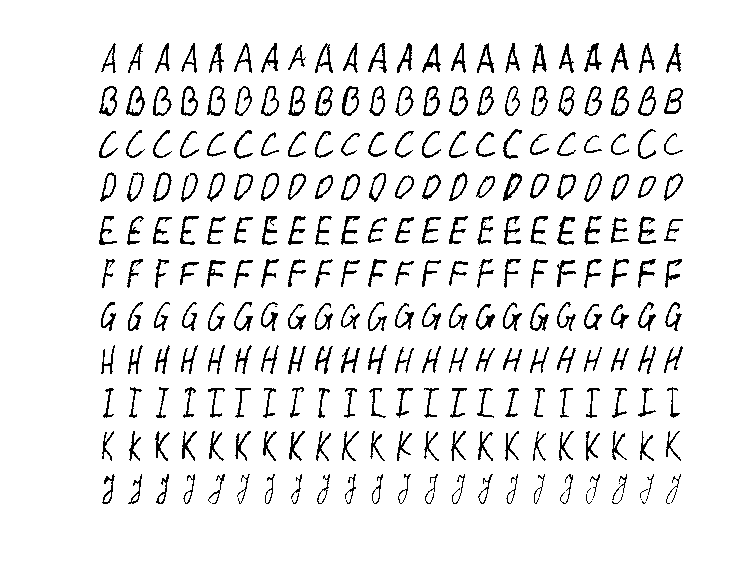

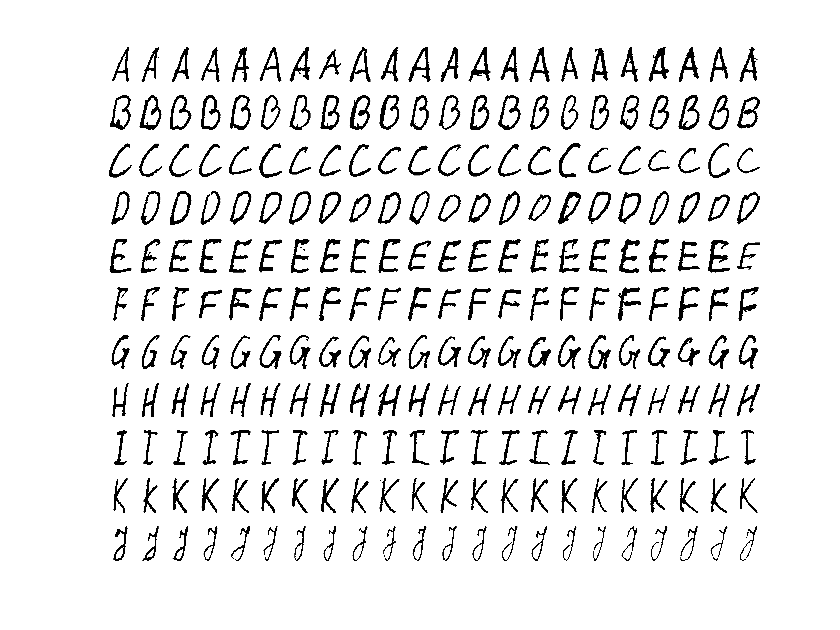

train_set_name = 'train_data.jpg';
train_features = pozymiai_raidems_atpazinti(train_set_name, 11);

## Development of character recognizer

take the features from cell-type variable and save into a matrix-type variable

train_feat_matr = cell2mat(train_features);
% sukuriama teisingø atsakymø matrica: 11 raidþiø, 8 eilutës mokymui
% create the matrices of correct answers for each line (number of matrices = number of symbol lines)
T = {[ones(1, 22); zeros(10, 22)], ...
    [zeros(1, 22); ones(1, 22); zeros(9, 22)], ...
    [zeros(2, 22); ones(1, 22); zeros(8, 22)], ...
    [zeros(3, 22); ones(1, 22); zeros(7, 22)], ...
    [zeros(4, 22); ones(1, 22); zeros(6, 22)], ...
    [zeros(5, 22); ones(1, 22); zeros(5, 22)], ...
    [zeros(6, 22); ones(1, 22); zeros(4, 22)], ...
    [zeros(7, 22); ones(1, 22); zeros(3, 22)], ...
    [zeros(8, 22); ones(1, 22); zeros(2, 22)], ...
    [zeros(9, 22); ones(1, 22); zeros(1, 22)], ...
    [zeros(10, 22); ones(1, 22)]};
% sukuriamas SBF tinklas duotiems P ir T sàryðiams
% create an RBF network for classification with 13 neurons, and sigma = 1
tinklas = newrb(train_feat_matr,T,0,1,13);

NEWRB, neurons = 0, MSE = 0.0826446


## Tinklo patikra | Test of the network (recognizer)

skaièiuojamas tinklo iðëjimas neþinomiems poþymiams estimate output of the network for unknown symbols (row, that were not used during training)

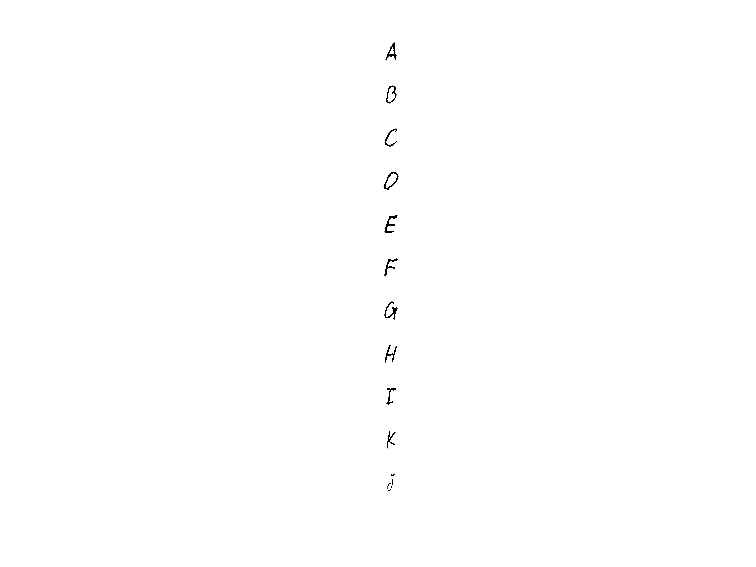

pavadinimas = 'first_test.jpg';
first_test_features = pozymiai_raidems_atpazinti(pavadinimas, 11);

P2 = cell2mat(first_test_features);
atsakymas = recognize(tinklas, P2);
disp(atsakymas)

ABCDEFGHIKJ


## Extract features of the test image

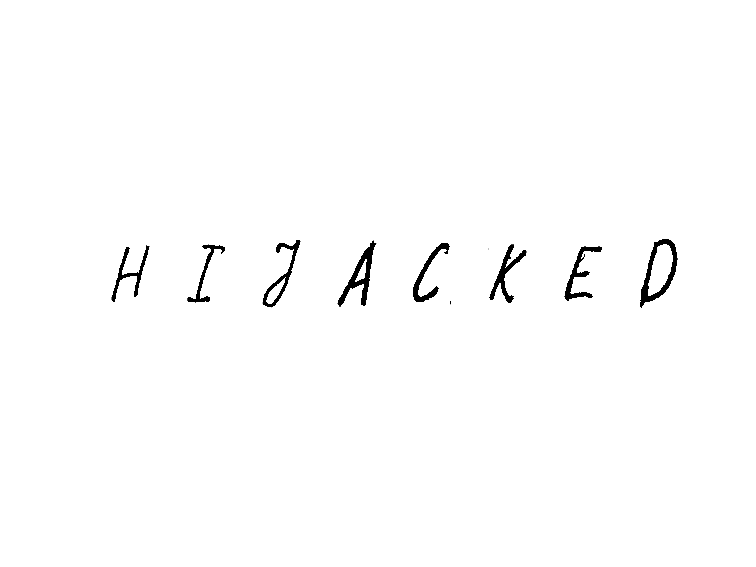

pavadinimas = 'test_data.jpg';
pozymiai_patikrai = pozymiai_raidems_atpazinti(pavadinimas, 1);

## Raidþiø atpaþinimas

## Perform letter/symbol recognition

poþymiai ið celiø masyvo perkeliami á matricà features from cell-variable are stored to matrix-variable

P2 = cell2mat(pozymiai_patikrai);
% skaièiuojamas tinklo iðëjimas neþinomiems poþymiams
% estimating neuran network output for newly estimated features
atsakymas = recognize(tinklas, P2);
disp(atsakymas)

HIJACAED


function atsakymas = recognize(network, features)
    Y2 = sim(network, features);
    [a2, b2] = max(Y2);
    raidziu_sk = size(features,2);
    atsakymas = zeros(raidziu_sk, 1);
    for k = 1:raidziu_sk
        switch b2(k)
            case 1
                atsakymas(k) = 'A';
            case 2
                atsakymas(k) = 'B';
            case 3
                atsakymas(k) = 'C';
            case 4
                atsakymas(k) = 'D';
            case 5
                atsakymas(k) = 'E';
            case 6
                atsakymas(k) = 'F';
            case 7
                atsakymas(k) = 'G';
            case 8
                atsakymas(k) = 'H';
            case 9
                atsakymas(k) = 'I';
            case 10
                atsakymas(k) = 'K';
            case 11
                atsakymas(k) = 'J';
        end
    end
    atsakymas = char(atsakymas)';
end